load ADC_Noise_Data.mat;

noise_mean = mean(data);
noise_max = max(data);
noise_min = min(data);
noise_span = noise_max - noise_min;
noise_std = std(double(data));

disp('Mean Reading: ');

Mean Reading: 


disp(noise_mean);

   8.1898e+03




disp('Max Reading: ');

Max Reading: 


disp(noise_max);

   8208




disp('Min Reading: ');

Min Reading: 


disp(noise_min);

   8175




disp('Span of Readings: ');

Span of Readings: 


disp(noise_span);

   33




disp('Std. Deviation of Readings: ');

Std. Deviation of Readings: 


disp(noise_std);

    3.4353



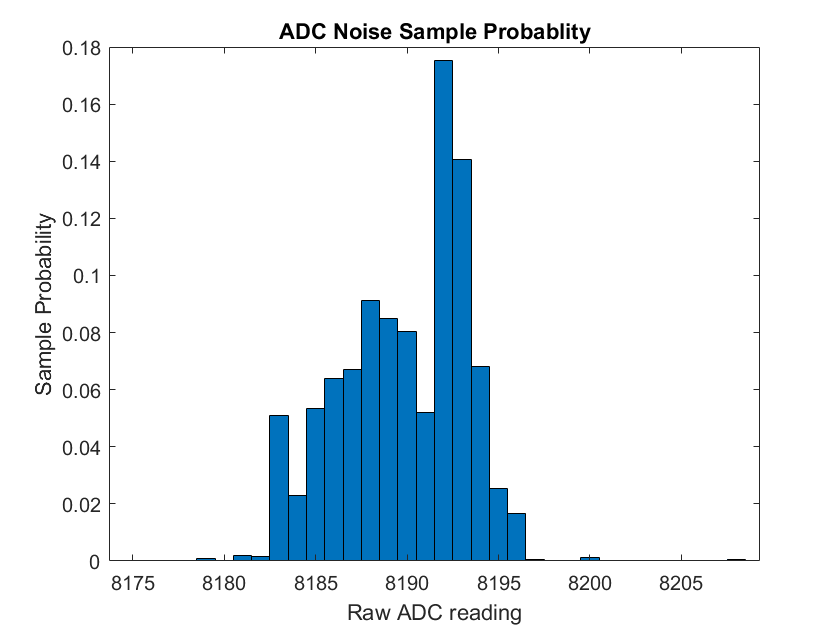

% Plot distribution of sample probablilty
[count, val] = groupcounts(data);
count = count/sum(count);

f1 = figure('Name','ADC Noise Sample Probablity');
bar(val, count, 1);
title('ADC Noise Sample Probablity');
xlabel('Raw ADC reading'); 
ylabel('Sample Probability'); 

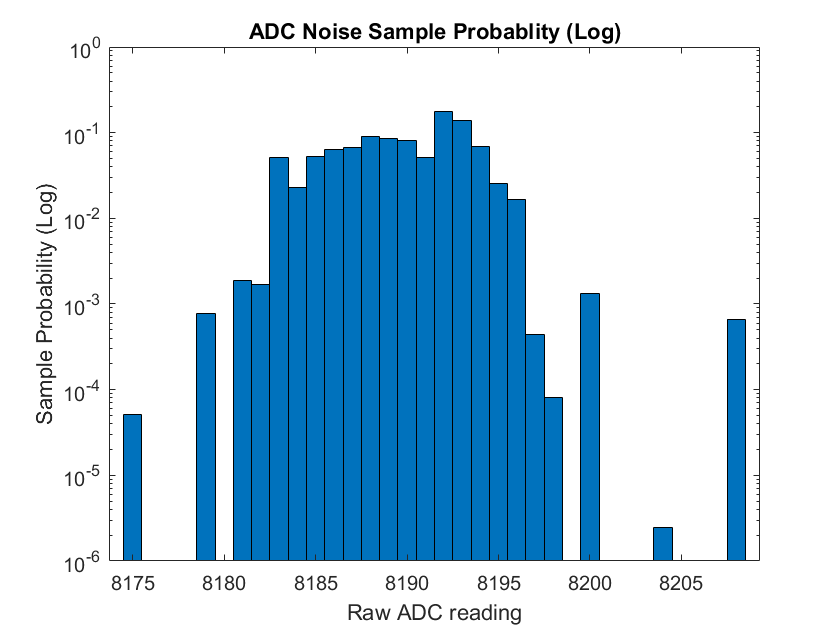


f2 = figure('Name','ADC Noise Sample Probablity (Log)');
bar(val, count, 1);
title('ADC Noise Sample Probablity (Log)');
xlabel('Raw ADC reading');
ylabel('Sample Probability (Log)');
set(gca, 'YScale', 'log');